%% MODELADO NUMERICO TRANSITORIO DEL TRANSPORTE DE CALOR 1D
% SDIRK4 (5 etapas) + Newton-Raphson + Gauss-Seidel
clear; clc; close all;

%% 0. CONFIGURACION PARA EVITAR WARNINGS DE FUENTES TEX
set(groot, 'defaultTextInterpreter', 'none');
set(groot, 'defaultAxesTickLabelInterpreter', 'none');
set(groot, 'defaultLegendInterpreter', 'none');

%% 1. PARAMETROS BASE DEL MODELO
L = 1.0;                 % Longitud de la linea de corriente (m)
N = 51;                  % Numero de nodos
dx = L / (N - 1);
x = linspace(0, L, N)';

v = 0.5;                 % Velocidad constante del fluido (m/s)
alpha0 = 0.01;           % Difusividad termica de referencia (m^2/s)
beta = 0.2;              % Coeficiente de variacion lineal
T0 = 0.0;                % Temperatura de referencia (C)

T1 = 100.0;              % Temperatura corriente libre (x=0)
TN = 0.0;                % Temperatura pared cilindro (x=L)

% AJUSTAR: con SDIRK4 completo, 2 s es tiempo fisico real y con v = 0.5 m/s
% el frente puede llegar a la pared (x = L). Se usa 0.5 s para que el frente
% quede dentro del dominio. Cambiar si se desea otro tiempo final.
T_final = 0.5;           % Tiempo total de simulacion (s)
h = 0.01;                % Paso de tiempo
num_pasos = round(T_final / h);

tol_nr = 1e-6;           % Tolerancia de Newton-Raphson
max_nr = 20;             % Maximo de iteraciones de Newton (igual que en la funcion)
max_gs = 500;            % Maximo de iteraciones de Gauss-Seidel (igual que en la funcion)

%% 2. COEFICIENTES SDIRK4 (5 etapas, gamma = 1/4)
gamma = 1/4;
A_rk = [ 1/4         0           0         0       0;
         1/2         1/4         0         0       0;
         17/50      -1/25        1/4       0       0;
         371/1360   -137/2720    15/544    1/4     0;
         25/24      -49/48       125/16   -85/12   1/4 ];
% La ultima fila coincide con los pesos b_i, por eso T^{n+1} = U_5.

%% 3. CONDICION INICIAL Y FIGURA
T = TN * ones(N, 1);
T(1) = T1;               % Condicion inicial

figure('Name', 'Evolucion del Frente Termico 1D', 'Position', [200, 200, 750, 450]);
h_plot = plot(x, T, 'b-', 'LineWidth', 2);
hold on;
yline((T1+TN)/2, 'k--', 'Temperatura Media (50 C)');
title('Transporte Transitorio de Calor 1D');
xlabel('Posicion x (m)');
ylabel('Temperatura T (C)');
grid on;
ylim([-5, 105]);

%% 4. BUCLE TEMPORAL (SDIRK4 DE 5 ETAPAS)
total_nr = 0;            % Iteraciones de Newton acumuladas
total_gs = 0;            % Iteraciones de Gauss-Seidel acumuladas
fallos_nr = 0;           % Etapas donde Newton no convergio
fallos_gs = 0;           % Etapas donde Gauss-Seidel llego al maximo

tic;
fprintf('Iniciando simulacion SDIRK4 + Newton-Raphson + Gauss-Seidel...\n');

Iniciando simulacion SDIRK4 + Newton-Raphson + Gauss-Seidel...


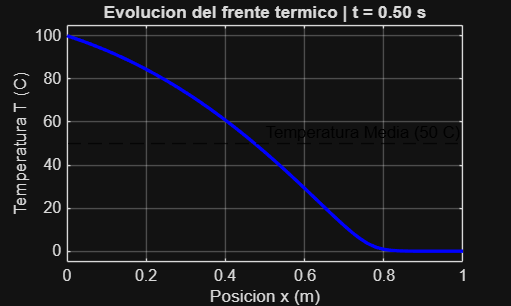


for n = 1:num_pasos
    t = n * h;
    T_old = T;
    F = zeros(N, 5);                 % Guarda f(U_j) de cada etapa
    U_i = T_old;

    for i = 1:5
        % Ecuacion (8): r_i = T^n + h * sum_{j<i} a_ij * f(U_j)
        r_i = T_old + h * F(:, 1:i-1) * A_rk(i, 1:i-1)';

        % Ecuacion (9)-(10): Newton-Raphson con Gauss-Seidel interno
        [U_i, iter_nr, gs_i] = newton_raphson_sdirk(U_i, r_i, h, gamma, v, alpha0, beta, T0, dx, N, tol_nr);

        total_nr = total_nr + iter_nr;
        total_gs = total_gs + gs_i;
        if iter_nr >= max_nr
            fallos_nr = fallos_nr + 1;
        end
        if gs_i >= max_gs * iter_nr
            fallos_gs = fallos_gs + 1;
        end

        F(:, i) = evaluar_f(U_i, v, alpha0, beta, T0, dx, N);
    end

    T = U_i;                         % T^{n+1} = U_5
    T(1) = T1; T(N) = TN;            % Fronteras Dirichlet fijas

    % Graficacion animada
    if mod(n, 5) == 0
        set(h_plot, 'YData', T);
        title(sprintf('Evolucion del frente termico | t = %.2f s', t));
        drawnow;
    end
end

tiempo_cpu = toc;

%% 5. CUANTIFICACION DEL FRENTE TERMICO Y RESULTADOS
T_media = (T1 + TN) / 2;

% Posicion del frente: primer nodo donde T <= T_media, con interpolacion lineal
idx = find(T <= T_media, 1);
if isempty(idx) || idx == 1
    x_frente = NaN;
    warning('El frente termico no se encuentra dentro del dominio.');
else
    x_frente = x(idx-1) + (T_media - T(idx-1)) * (x(idx) - x(idx-1)) / (T(idx) - T(idx-1));
end

fprintf('\n=======================================================\n');

fprintf(' RESULTADOS DE LA SIMULACION COMPLETA \n');

 RESULTADOS DE LA SIMULACION COMPLETA 


fprintf('=======================================================\n');

fprintf('Tiempo fisico simulado: %.3f s (%d pasos, h = %.4f s)\n', num_pasos*h, num_pasos, h);

Tiempo fisico simulado: 0.500 s (50 pasos, h = 0.0100 s)


fprintf('Tiempo de procesamiento CPU: %.4f segundos\n', tiempo_cpu);

Tiempo de procesamiento CPU: 4.5403 segundos


fprintf('Iteraciones de Newton totales: %d\n', total_nr);

Iteraciones de Newton totales: 787


fprintf('Iteraciones de Gauss-Seidel totales: %d\n', total_gs);

Iteraciones de Gauss-Seidel totales: 9140


fprintf('Etapas sin convergencia (Newton / Gauss-Seidel): %d / %d\n', fallos_nr, fallos_gs);

Etapas sin convergencia (Newton / Gauss-Seidel): 0 / 0


fprintf('Posicion final del frente termico (T = %.1f C): x = %.4f m\n', T_media, x_frente);

Posicion final del frente termico (T = 50.0 C): x = 0.4739 m


fprintf('=======================================================\n');